clc; clear; close all;

%% 1. MATERIAL PROPERTIES (Inconel 718 Baseline parameters)
E = 200e9;              % Young's Modulus (Pa)
sigma_f_prime = 1100e6; % Fatigue strength coefficient (Pa)
epsilon_f_prime = 0.55; % Fatigue ductility coefficient
b = -0.08;              % Fatigue strength exponent
c = -0.65;              % Fatigue ductility exponent

%% 2. IMPORT EXPORTED ANSYS TEXT FILES (2-Column Mode)
fprintf('Reading ANSYS 2-column data files...\n');

Reading ANSYS 2-column data files...



% Import files directly as numeric matrices, ignoring any non-numeric text headers
stressData = readmatrix('stress.txt');
strainData = readmatrix('strain.txt');
tempData   = readmatrix('temperature.txt');

%% 3. EXTRACT VALUES BY POSITION
% Column 1 is Node ID, Column 2 is the actual data value
node_ids    = stressData(:, 1);
stress_vals = stressData(:, 2); 
strain_vals = strainData(:, 2);
temp_vals   = tempData(:, 2);

fprintf('Successfully loaded data for %d structural nodes.\n', length(node_ids));

Successfully loaded data for 459957 structural nodes.



%% 4. CRITICAL FAILURE NODE IDENTIFICATION
[max_stress, max_idx] = max(stress_vals);
crit_node   = node_ids(max_idx);
crit_strain = strain_vals(max_idx);
crit_temp   = temp_vals(max_idx);

fprintf('\n================ CRITICAL NODE ANALYSIS ================ \n');


================ CRITICAL NODE ANALYSIS ================ 


fprintf('Critical Failure Location Found at Node ID: %d\n', round(crit_node));

Critical Failure Location Found at Node ID: 2559


fprintf('Peak von Mises Stress: %.2f MPa\n', max_stress / 1e6);

Peak von Mises Stress: 134.96 MPa


fprintf('Corresponding Strain: %.6f\n', crit_strain);

Corresponding Strain: 0.000675


fprintf('Local Operating Temperature: %.2f °C\n', crit_temp);

Local Operating Temperature: 350.00 °C



%% 5. FATIGUE LIFE PREDICTION VIA MANSON-COFFIN (Low & High Cycle Check)
strain_amplitude = crit_strain / 2; 

% If peak stress is low, the blade is in the High-Cycle Fatigue (HCF) regime
manson_coffin = @(Nf) (sigma_f_prime/E)*(2*Nf)^b + epsilon_f_prime*(2*Nf)^c - strain_amplitude;

% Check if the strain amplitude is small enough to indicate infinite life
if strain_amplitude < (sigma_f_prime / E) * (2*1e7)^b
    Nf_solved = Inf;
else
    options = optimset('Display','off');
    Nf_solved = fzero(manson_coffin, [1, 1e9], options);
end

fprintf('\n================== LIFE ESTIMATION ================== \n');


================== LIFE ESTIMATION ================== 


if isinf(Nf_solved) || isnan(Nf_solved)
    fprintf('Fatigue Regime: High-Cycle Fatigue (HCF) / Infinite Life\n');
    fprintf('Predicted Cycles Until Crack Initiation: >10,000,000 cycles\n');
    fprintf('Conclusion: Design is structurally safe against operational fatigue loading.\n');
else
    fprintf('Fatigue Regime: Low-Cycle Fatigue (LCF)\n');
    fprintf('Predicted Cycles Until Crack Initiation: %d cycles\n', round(Nf_solved));
end

Fatigue Regime: High-Cycle Fatigue (HCF) / Infinite Life


Predicted Cycles Until Crack Initiation: >10,000,000 cycles


Conclusion: Design is structurally safe against operational fatigue loading.


fprintf('======================================================== \n');

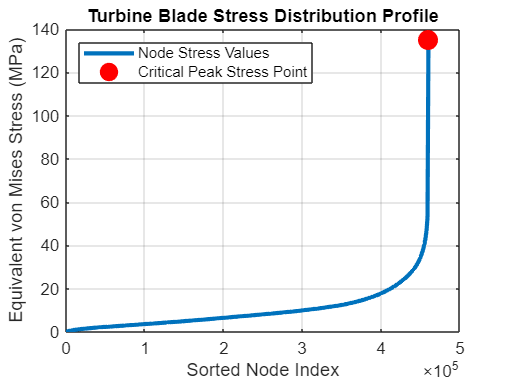


%% 6. HIGH-FIDELITY PROJECT VISUALIZATION
figure('Name', 'Turbine Blade Node Analysis', 'Color', 'w');

% Sort data for a clean distribution curve
sorted_stress = sort(stress_vals / 1e6);

plot(sorted_stress, 'LineWidth', 2.5, 'Color', [0 0.4470 0.7410]);
hold on;
plot(length(sorted_stress), max_stress/1e6, 'ro', 'MarkerSize', 10, 'LineWidth', 2, 'MarkerFaceColor', 'r');

grid on;
title('Turbine Blade Stress Distribution Profile');
xlabel('Sorted Node Index');
ylabel('Equivalent von Mises Stress (MPa)');
legend('Node Stress Values', 'Critical Peak Stress Point', 'Location', 'NorthWest');


%% 1. MATERIAL PROPERTIES (Inconel 718 Baseline parameters)
E = 200e9;              % Young's Modulus (Pa)
sigma_f_prime = 1100e6; % Fatigue strength coefficient (Pa)
epsilon_f_prime = 0.55; % Fatigue ductility coefficient
b = -0.08;              % Fatigue strength exponent
c = -0.65;              % Fatigue ductility exponent

% Larson-Miller Constants for Creep Life calculation (Inconel 718)
C_LMP = 20;             
% Polynomial coefficients mapping Log10(Stress) to LMP values
% Format: LMP = p1*log10(sigma)^2 + p2*log10(sigma) + p3
p1 = -1150; p2 = 4500; p3 = 18500; 

%% 2. IMPORT ALL EXPORTED ANSYS TEXT FILES
fprintf('Reading full ANSYS multi-field data arrays...\n');

Reading full ANSYS multi-field data arrays...



stressData = readmatrix('stress.txt');
strainData = readmatrix('strain.txt');
tempData   = readmatrix('temperature.txt');
defData    = readmatrix('deformation.txt'); % Ensure this file is in your folder

%% 3. EXTRACT VALUES BY POSITION
node_ids    = stressData(:, 1);
stress_vals = stressData(:, 2); 
strain_vals = strainData(:, 2);
temp_vals   = tempData(:, 2);
def_vals    = defData(:, 2);    % Total Deformation (mm or m)

fprintf('Successfully synchronized data across %d structural nodes.\n', length(node_ids));

Successfully synchronized data across 459957 structural nodes.



%% 4. MULTI-VARIABLE CRITICAL NODE LOCATIONS
[max_stress, s_idx] = max(stress_vals);
[max_temp, t_idx]   = max(temp_vals);
[max_def, d_idx]    = max(def_vals);

fprintf('\n================== MULTIPHYSICS FIELD EXTREMES ================== \n');


================== MULTIPHYSICS FIELD EXTREMES ================== 


fprintf('Peak von Mises Stress : %.2f MPa  (at Node %d)\n', max_stress / 1e6, node_ids(s_idx));

Peak von Mises Stress : 134.96 MPa  (at Node 2559)


fprintf('Peak Operating Temp   : %.2f °C   (at Node %d)\n', max_temp, node_ids(t_idx));

Peak Operating Temp   : 1300.00 °C   (at Node 147)


fprintf('Max Total Deformation : %.4f mm   (at Node %d)\n', max_def, node_ids(d_idx));

Max Total Deformation : 0.0002 mm   (at Node 658)



%% 5. FATIGUE LIFE PREDICTION VIA MANSON-COFFIN (At Peak Stress Node)
crit_strain = strain_vals(s_idx);
strain_amplitude = crit_strain / 2; 
manson_coffin = @(Nf) (sigma_f_prime/E)*(2*Nf)^b + epsilon_f_prime*(2*Nf)^c - strain_amplitude;

if strain_amplitude < (sigma_f_prime / E) * (2*1e7)^b
    Nf_solved = Inf;
else
    options = optimset('Display','off');
    Nf_solved = fzero(manson_coffin, [1, 1e9], options);
end

%% 6. CREEP LIFE EVALUATION VIA LARSON-MILLER (At Peak Temperature Node)
% Convert local temperature to Kelvin for thermodynamic creep models
T_kelvin = max_temp + 273.15; 
stress_at_max_t = stress_vals(t_idx) / 1e6; % Stress in MPa at the hot zone

if stress_at_max_t <= 0, stress_at_max_t = 1.0; end % Prevent log10 errors

% Calculate Larson-Miller Parameter value from empirical curve fit
LMP_val = p1*(log10(stress_at_max_t))^2 + p2*log10(stress_at_max_t) + p3;

% Solve for Time to Rupture (t_rupture in hours) from LMP = T * (C + log10(t))
log10_t = (LMP_val / T_kelvin) - C_LMP;
t_rupture = 10^log10_t;

%% 7. COMMAND WINDOW REPORT GENERATION
fprintf('\n================== CRITICAL HEALTH ASSESSMENT ================== \n');


================== CRITICAL HEALTH ASSESSMENT ================== 


if isinf(Nf_solved) || isnan(Nf_solved)
    fprintf('Fatigue Regime   : High-Cycle Fatigue (HCF) / Safe Elastic Limits\n');
    fprintf('Fatigue Lifespan : >10,000,000 startup/shutdown cycles\n');
else
    fprintf('Fatigue Regime   : Low-Cycle Fatigue (LCF)\n');
    fprintf('Fatigue Lifespan : %d operational cycles\n', round(Nf_solved));
end

Fatigue Regime   : High-Cycle Fatigue (HCF) / Safe Elastic Limits


Fatigue Lifespan : >10,000,000 startup/shutdown cycles



if t_rupture > 100000
    fprintf('Creep Resistance : Excellent (Extremely low structural thermal risk)\n');
    fprintf('Creep Rupture Time: >100,000 hours of continuous operation\n');
else
    fprintf('Creep Resistance : Thermal-stress constrained\n');
    fprintf('Creep Rupture Time: %.1f hours of continuous operation\n', t_rupture);
end

Creep Resistance : Thermal-stress constrained


Creep Rupture Time: 0.0 hours of continuous operation


fprintf('================================================================ \n');

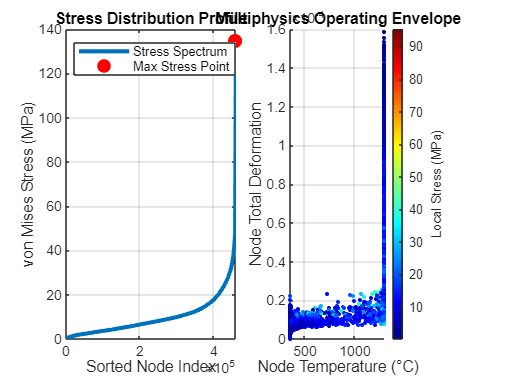


%% 8. HIGH-FIDELITY COMPREHENSIVE PROJECT PLOTS
figure('Name', 'Multi-Field Structural Analysis Dashboard', 'Color', 'w');

% Subplot 1: Sorted Stress Distribution Curve
subplot(1,2,1);
plot(sort(stress_vals / 1e6), 'LineWidth', 2.5, 'Color', [0 0.4470 0.7410]);
grid on; hold on;
plot(length(stress_vals), max_stress/1e6, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
title('Stress Distribution Profile');
xlabel('Sorted Node Index'); ylabel('von Mises Stress (MPa)');
legend('Stress Spectrum', 'Max Stress Point', 'Location', 'NorthWest');

% Subplot 2: Temperature vs. Mechanical Deflection Correlation
subplot(1,2,2);
% Sample data to keep plot rendering lightweight if dealing with massive datasets
sample_rate = max(1, round(length(node_ids)/5000)); 
scatter(temp_vals(1:sample_rate:end), def_vals(1:sample_rate:end), 6, stress_vals(1:sample_rate:end)/1e6, 'filled');
grid on;
colorbar; colormap(gca, 'jet');
title('Multiphysics Operating Envelope');
xlabel('Node Temperature (°C)'); ylabel('Node Total Deformation');
h = colorbar; ylabel(h, 'Local Stress (MPa)');



%% 1. MATERIAL PROPERTIES (Inconel 718 Baseline parameters)
E = 200e9;              % Young's Modulus (Pa)
sigma_f_prime = 1100e6; % Fatigue strength coefficient (Pa)
epsilon_f_prime = 0.55; % Fatigue ductility coefficient
b = -0.08;              % Fatigue strength exponent
c = -0.65;              % Fatigue ductility exponent

% Larson-Miller Constants for Creep Life calculation
C_LMP = 20;             
p1 = -1150; p2 = 4500; p3 = 18500; 

%% 2. IMPORT ALL EXPORTED ANSYS TEXT FILES (Including Heat Flux)
fprintf('Reading full ANSYS multi-field data arrays...\n');

Reading full ANSYS multi-field data arrays...



stressData = readmatrix('stress.txt');
strainData = readmatrix('strain.txt');
tempData   = readmatrix('temperature.txt');
defData    = readmatrix('deformation.txt');
fluxData   = readmatrix('total heat flux.txt'); % New Heat Flux Data

%% 3. EXTRACT VALUES BY POSITION
node_ids    = stressData(:, 1);
stress_vals = stressData(:, 2); 
strain_vals = strainData(:, 2);
temp_vals   = tempData(:, 2);
def_vals    = defData(:, 2);    
flux_vals   = fluxData(:, 2);    % Total Heat Flux (W/m²)

fprintf('Successfully synchronized data across %d structural nodes.\n', length(node_ids));

Successfully synchronized data across 459957 structural nodes.



%% 4. MULTI-VARIABLE FIELD EXTREMES (Now including Thermal Management)
[max_stress, s_idx] = max(stress_vals);
[max_temp, t_idx]   = max(temp_vals);
[max_def, d_idx]    = max(def_vals);
[max_flux, f_idx]   = max(flux_vals); % Peak thermal energy transfer

fprintf('\n================== MULTIPHYSICS FIELD EXTREMES ================== \n');


================== MULTIPHYSICS FIELD EXTREMES ================== 


fprintf('Peak von Mises Stress : %.2f MPa  (at Node %d)\n', max_stress / 1e6, node_ids(s_idx));

Peak von Mises Stress : 134.96 MPa  (at Node 2559)


fprintf('Peak Operating Temp   : %.2f °C   (at Node %d)\n', max_temp, node_ids(t_idx));

Peak Operating Temp   : 1300.00 °C   (at Node 147)


fprintf('Max Total Deformation : %.4f mm   (at Node %d)\n', max_def, node_ids(d_idx));

Max Total Deformation : 0.0002 mm   (at Node 658)


fprintf('Peak Total Heat Flux  : %.2f kW/m² (at Node %d)\n', max_flux / 1000, node_ids(f_idx));

Peak Total Heat Flux  : 60110.00 kW/m² (at Node 444)



%% 5. LIFETIME PREDICTION SOLVERS (Fatigue & Creep)
strain_amplitude = strain_vals(s_idx) / 2; 
manson_coffin = @(Nf) (sigma_f_prime/E)*(2*Nf)^b + epsilon_f_prime*(2*Nf)^c - strain_amplitude;

if strain_amplitude < (sigma_f_prime / E) * (2*1e7)^b
    Nf_solved = Inf;
else
    options = optimset('Display','off');
    Nf_solved = fzero(manson_coffin, [1, 1e9], options);
end

% Creep calculation at max temperature zone
T_kelvin = max_temp + 273.15; 
stress_at_max_t = stress_vals(t_idx) / 1e6; 
if stress_at_max_t <= 0, stress_at_max_t = 1.0; end 
LMP_val = p1*(log10(stress_at_max_t))^2 + p2*log10(stress_at_max_t) + p3;
t_rupture = 10^((LMP_val / T_kelvin) - C_LMP);

%% 6. PRINT FINAL REPORT
fprintf('\n================== CRITICAL HEALTH ASSESSMENT ================== \n');


================== CRITICAL HEALTH ASSESSMENT ================== 


if isinf(Nf_solved) || isnan(Nf_solved)
    fprintf('Fatigue Regime   : High-Cycle Fatigue (HCF) / Safe Elastic Limits\n');
else
    fprintf('Fatigue Regime   : Low-Cycle Fatigue (LCF) [%d cycles]\n', round(Nf_solved));
end

Fatigue Regime   : High-Cycle Fatigue (HCF) / Safe Elastic Limits



if t_rupture > 100000
    fprintf('Creep Resistance : Excellent (>100,000 continuous hours)\n');
else
    fprintf('Creep Rupture Time: %.1f hours of continuous operation\n', t_rupture);
end

Creep Rupture Time: 0.0 hours of continuous operation


fprintf('================================================================ \n');

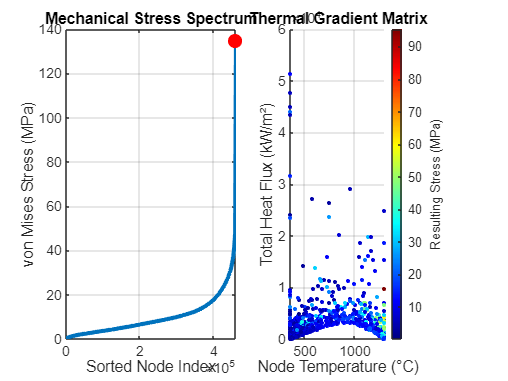


%% 7. HIGH-FIDELITY PROJECT VISUALIZATION
figure('Name', 'Turbine Blade Multiphysics Dashboard', 'Color', 'w');

% Plot 1: Mechanical Loading Profile
subplot(1,2,1);
plot(sort(stress_vals / 1e6), 'LineWidth', 2.5, 'Color', [0 0.4470 0.7410]);
grid on; hold on;
plot(length(stress_vals), max_stress/1e6, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
title('Mechanical Stress Spectrum');
xlabel('Sorted Node Index'); ylabel('von Mises Stress (MPa)');

% Plot 2: Thermal Management Matrix (Heat Flux vs Temperature)
subplot(1,2,2);
sample_rate = max(1, round(length(node_ids)/5000)); % Downsample for performance
scatter(temp_vals(1:sample_rate:end), flux_vals(1:sample_rate:end)/1000, 6, stress_vals(1:sample_rate:end)/1e6, 'filled');
grid on; colorbar; colormap(gca, 'jet');
title('Thermal Gradient Matrix');
xlabel('Node Temperature (°C)'); ylabel('Total Heat Flux (kW/m²)');
h = colorbar; ylabel(h, 'Resulting Stress (MPa)');